%make a mesh grid
a = -2:2;
[A,B] = meshgrid(a)

A =     -2    -1     0     1     2
    -2    -1     0     1     2
    -2    -1     0     1     2
    -2    -1     0     1     2
    -2    -1     0     1     2


B =     -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1
     0     0     0     0     0
     1     1     1     1     1
     2     2     2     2     2


% c = ab/a+b

%make a larger mesh grid
p = 10:10:200;
[P,Q] = meshgrid(p);
P

P =     10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200
    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200
    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200
    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200
    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200
    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200
    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200
    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200
    10    20    30    40    

Q

Q =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10
    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20
    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30
    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40
    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50
    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60
    70    70    70    70    70    70    70    70    70    70    70    70    70    70    70    70    70    70    70    70
    80    80    80    80    80    80    80    80    80    80    80    80    80    80    80    80    80    80    80    80
    90    90    90    90    

mul = P.*Q

mul =          100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800        1900        2000
         200         400         600         800        1000        1200        1400        1600        1800        2000        2200        2400        2600        2800        3000        3200        3400        3600        3800        4000
         300         600         900        1200        1500        1800        2100        2400        2700        3000        3300        3600        3900        4200        4500        4800        5100        5400        5700        6000
         400         800        1200        1600        2000        2400        2800        3200        3600        4000        4400        4800        5200        5600        6000        6400        6800        7200        7600        8000
         500        1000      

sum = P+Q

sum =     20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210
    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220
    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230
    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240
    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250
    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260
    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270
    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280
   100   110   120   130  

R = (P.*Q)./(P+Q)

R =     5.0000    6.6667    7.5000    8.0000    8.3333    8.5714    8.7500    8.8889    9.0000    9.0909    9.1667    9.2308    9.2857    9.3333    9.3750    9.4118    9.4444    9.4737    9.5000    9.5238
    6.6667   10.0000   12.0000   13.3333   14.2857   15.0000   15.5556   16.0000   16.3636   16.6667   16.9231   17.1429   17.3333   17.5000   17.6471   17.7778   17.8947   18.0000   18.0952   18.1818
    7.5000   12.0000   15.0000   17.1429   18.7500   20.0000   21.0000   21.8182   22.5000   23.0769   23.5714   24.0000   24.3750   24.7059   25.0000   25.2632   25.5000   25.7143   25.9091   26.0870
    8.0000   13.3333   17.1429   20.0000   22.2222   24.0000   25.4545   26.6667   27.6923   28.5714   29.3333   30.0000   30.5882   31.1111   31.5789   32.0000   32.3810   32.7273   33.0435   33.3333
    8.3333   14.2857   18.7500   22.2222   25.0000   27.2727   29.1667   30.7692   32.1429   33.3333   34.3750   35.2941   36.1111   36.8421   37.5000   38.0952   38.6364   39.1304   39.5833  

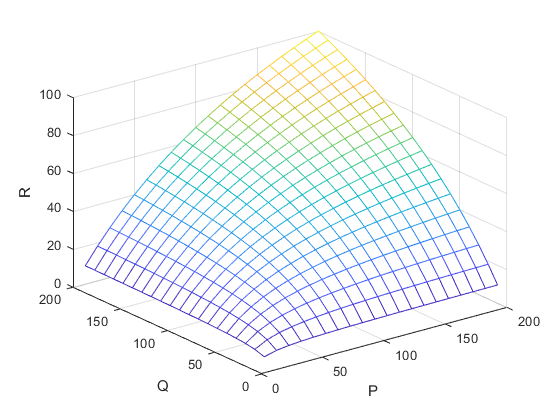

mesh(P,Q,R)
xlabel('P'), ylabel('Q'), zlabel('R')